## H4- Detecció pedres

### Pre-processat

El primer pas que hem fet ha sigut fer una sèrie de procesos a la imatge original per tal de facilitar-nos la detecció de les pedres. 

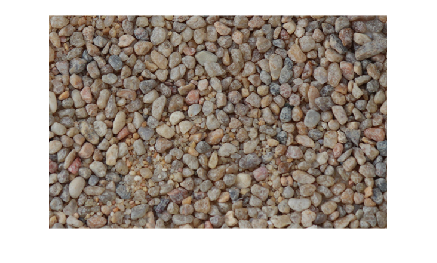

Original = imread("pedretes.png");
imshow(Original);

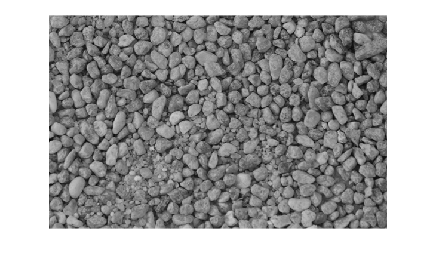

I = rgb2gray(Original);
imshow(I);

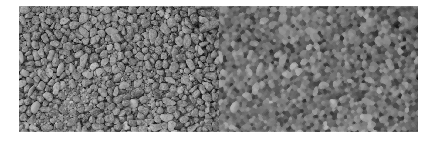


SE = strel('disk',4);
IO = imopen(I,SE);
IOC = imclose(IO,SE);
montage({I,IOC});

#### Imatge de marques

A continuació calculem els màxims locals de l'imatge, que simulen els centres de els pedres.

Després de detectar aquests màxims hem calculat el SKIZ mitjançant aquests màxims. A més, hem calculat l'imatge de marques, obtinguda invertint l'imatge per tal que els màxims passin a ser els mínims.

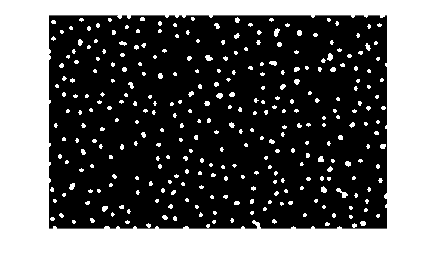

% Màxims regionals de l'imatge
MARK_C = imregionalmax(IOC);
imshow(MARK_C);

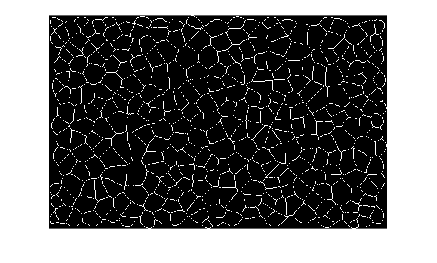

% SKIZ
SK = bwskel(not(MARK_C));
MARK_B = bwmorph(SK,'spur',Inf);
MARK_B = MARK_B & not(bwhitmiss(MARK_B,[-1,-1,-1;-1,1,-1;-1,-1,-1]));
imshow(MARK_B);

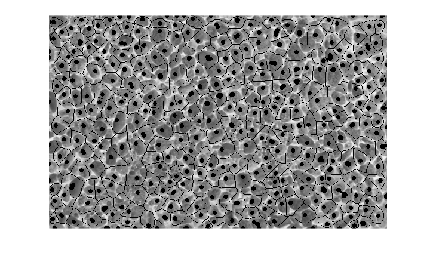

% Imatge de marques
MARKERS = (255-I) .* uint8(not(MARK_B)) .* uint8(not(MARK_C));
imshow(MARKERS);

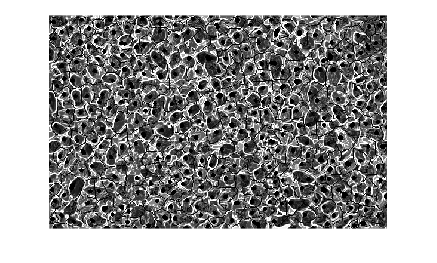

N = imimposemin(G, MARK_B|MARK_C);
imshow(N,[]);

#### Imatge gradient

Obtenim l'imatge gradient, necessària per el càlcul del watershed.

G = uint8(imgradient(I));

#### Watershed

Un cop calcualdes l'imatge de marques i l'imatge gradient, procedim a fer el watershed.

Tot seguit hem utilitzat la tècnica de watershed utilitzant la imatge de marques dels màxims amb el seu SKIZ, i la image de gradients.

Els punts on el watershed és 0, són els punts on els dos fronts d'aigua es troben, que correspon a les fronteres de les pedres. 

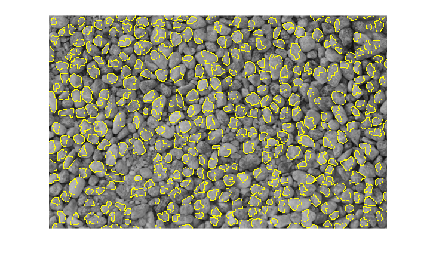

WS = watershed(N);
IB = WS == 0;
RGB = imoverlay(I, IB);

imshow(RGB);

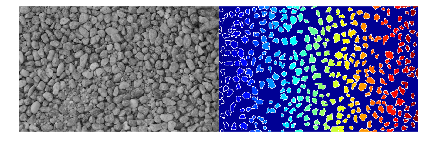

montage({I,label2rgb(WS)});

#### Binarització

Tot seguit, utilitzant els components connexos hem obtingut aquestes fronteres emplenades.

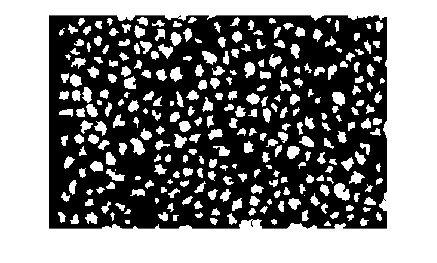

K = bwlabel(WS);
K = K > 15;
imshow(K,[]);

#### Eliminar pedres de les bores

 Per tal de descartar pedres que surten a les bores de la imatge, hem utilitzat una reconstrucció amb una imatge de marques que envolta tot el marc.

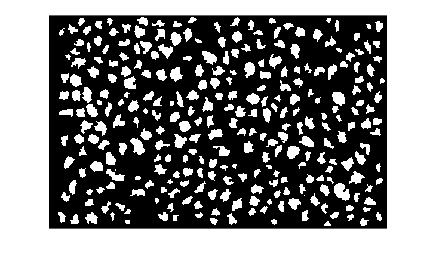

MARK = false(size(K));
MARK(1,:) = 1;
MARK(:,1) = 1;
MARK(end,:) = 1;
MARK(:,end) = 1;
REC = imreconstruct(MARK,K,8);
S = K&not(REC);
imshow(S,[]);

#### Esborrar pedres de fora de l'interval donat per l'usuari

 Finalment, de manera iterativa eliminem les pedres que no tenen la mida desitjada, és a dir, que no es troben dins del nostre interval. 

MAX_SIZE i MIN_SIZE són dades programables per l'usuari per tal d'acotar la "cerca" a les mides de pedres que es vulgui. El que fem és, per cada pedra, mirem el nombre de píxels que ocupa i si no està entre MIN_SIZE i MAX_SIZE no la contem; en canvi si hi està la marquem de color lila per tal que es pugui visualitzar als resultats.

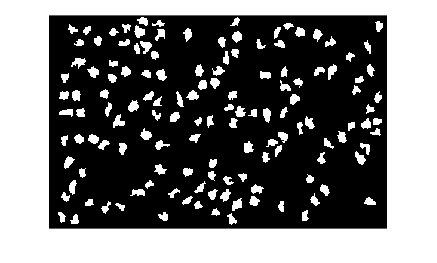

C = bwconncomp(S);
n_pixels = cellfun(@numel,C.PixelIdxList);
MIN_SIZE = 125;  %% Tamany Mínim
MAX_SIZE = 250;  %% Tamany Màxim
S2 = S;

n_pedres = 0;
[f, c] = size(n_pixels);
for i=1 : c
    if (n_pixels(1,i) < MIN_SIZE || n_pixels(1,i) > MAX_SIZE)
        S2(C.PixelIdxList{i}) = 0;
    else
        n_pedres = n_pedres + 1;
    end
end
imshow(S2,[]);

#### Presentació de resultats (nº de pedres)

L'última cosa que fem és representar les pedres seleccionades amb el color morat superposat amb la imatge original a més de mostrar el nombre total de pedres detectat (n_pedres).

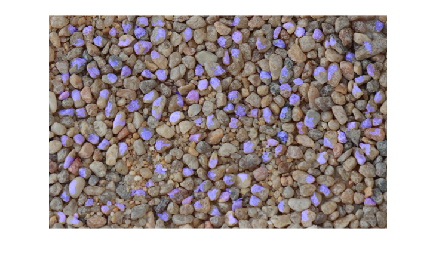

Original(:,:,3) = uint8(Original(:,:,3) + 100*uint8(S2(:,:)));
imshow(Original);

n_pedres

n_pedres = 136